if Comparative_graphs == true

## **Graph 14: Heat transport analysis**

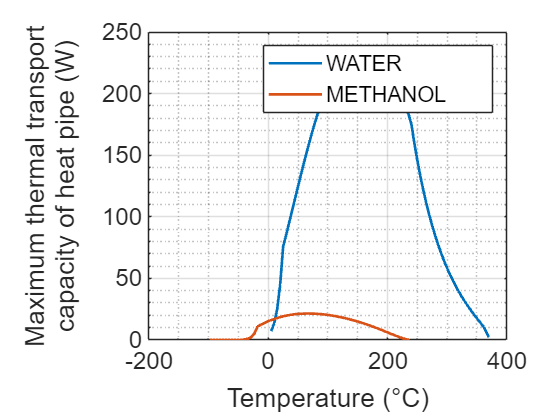

% Create figure
figure14 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

Qcap_t(Qcap_t==100000) = 0;
Tx(Tx==0) = nan;

axes1 = axes('Parent',figure14);
hold(axes1,'on');
for x1 = 1:n
plot1 = plot(Tx(:,x1),[Qmin_ant(:,x1)],'Parent',axes1,'LineWidth',2);
set(plot1,'DisplayName',NAME(x1));
end

% Create ylabel
ylabel({'Maximum thermal transport' ;'capacity of heat pipe (W)'});

% Create xlabel
xlabel({'Temperature (°C)'});

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[250 550]);
box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')
% Create legend
legend(axes1,'show');

## **Graph 15: Vapour Pressure Analysis**

x5 = 1;


figure15 = figure('NumberTitle','off','Name','Figure','Color',[1 1 1],...
    'OuterPosition',[31 137 1128 914]);
% Create axes
axes1 = axes('Parent',figure15);
hold(axes1,'on');
for x5 = 1:n
plot1 = plot(Tx(:,x5),Pvx(:,x5),'Parent',axes1,'LineWidth',2);
set(plot1(1),'DisplayName',string(NAME(x5)));
x5 = x5+1;
end
%set(plot1(1),'DisplayName','');

% Create ylabel
ylabel({'Vapour Pressure (Bar) '});

% Create xlabel
xlabel({'Temperature (°C)'});

box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on','YScale','log');
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','southeast');

## Graph 16: Merit Analysis 

x5 = 1;


figure16 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);
% Create axes
axes1 = axes('Parent',figure16);
hold(axes1,'on');
for x5 = 1:n
plot1 = plot(Tx(:,x5),htc(:,x5),'Parent',axes1,'LineWidth',2);
set(plot1(1),'DisplayName',string(NAME(x5)));
x5 = x5+1;
end
%set(plot1(1),'DisplayName','');

% Create ylabel
ylabel({'Liquid transport factor (W/m^2)'});

% Create xlabel
xlabel({'Temperature (°C)'});

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[250 550]);
box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorTick','on','YGrid','on',...
    'YMinorTick','on','YScale','log');
% Create legend
legend1 = legend(axes1,'show');
set(legend1,'Location','southwest');

end